A= imread("E:\Study\DIP\Lab_exp\cameraman.jpg");
A =rgb2gray(A)

A = 512×512 uint8 matrix
   159   158   158   157   156   155   155   155   158   158   158   158   158   158   158   158   156   156   157   157   156   157   158   159   159   160   159   160   162   159   157   160   165   162   160   161   161   160   160   161   163   162   161   162   164   165   164   162   160   161
   156   156   157   158   158   157   156   155   158   158   158   158   158   158   158   158   157   157   157   157   156   156   158   159   158   159   158   159   162   159   156   160   164   162   160   161   161   160   160   161   162   161   160   161   163   163   162   161   160   161
   156   156   156   156   157   157   157   157   158   158   158   158   158   158   158   158   158   158   158   157   156   156   157   158   158   159   158   158   161   158   156   159   164   161   160   161   161   160   159   160   161   160   159   160   161   162   161   160   160   161
   159   157   155   154   154   156   158   159   158   158   158   158

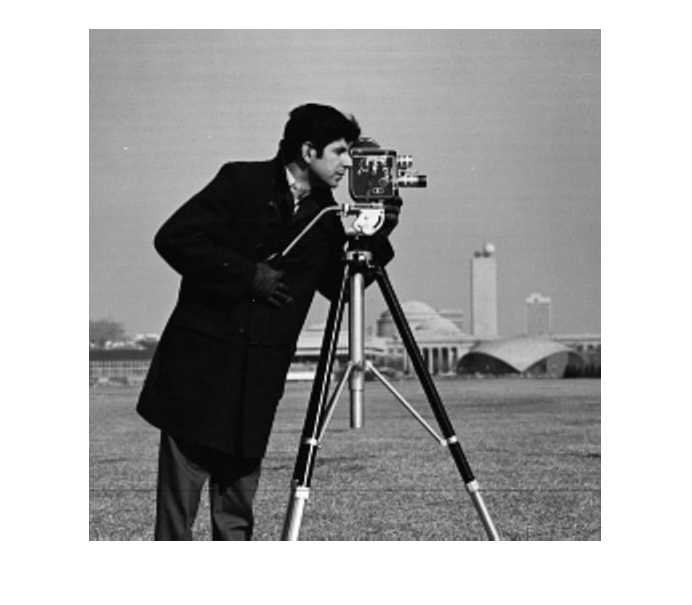


figure;
imshow(A);

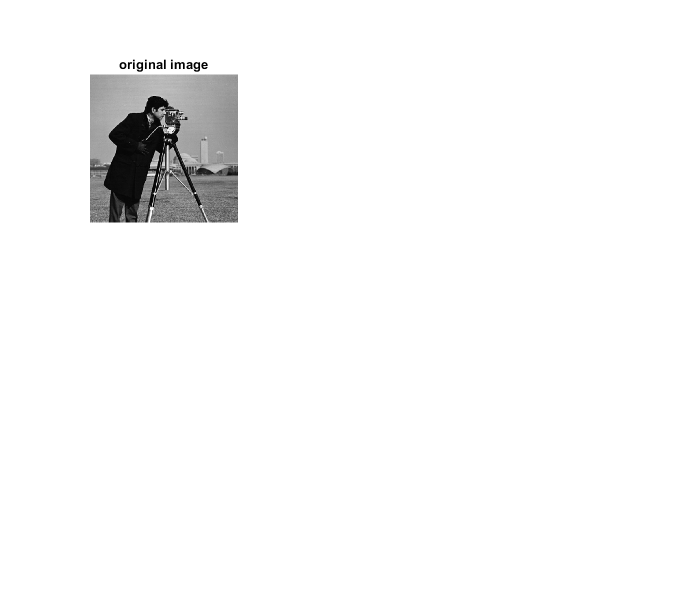

b = double(A);
subplot(2,3,1)
imshow(A);
title('original image');

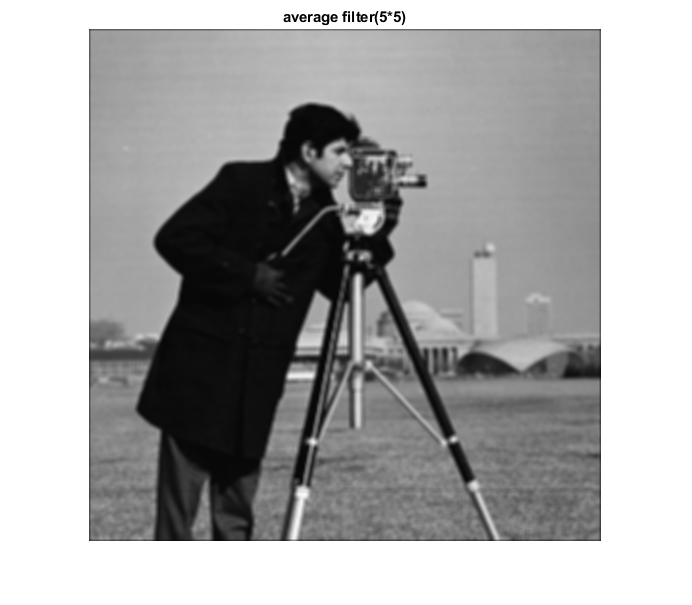


h2=1/25*ones(5,5);

b1=conv2(double(A),double(h2),'same');
figure;
imshow(uint8(b1));
title('average filter(5*5)');

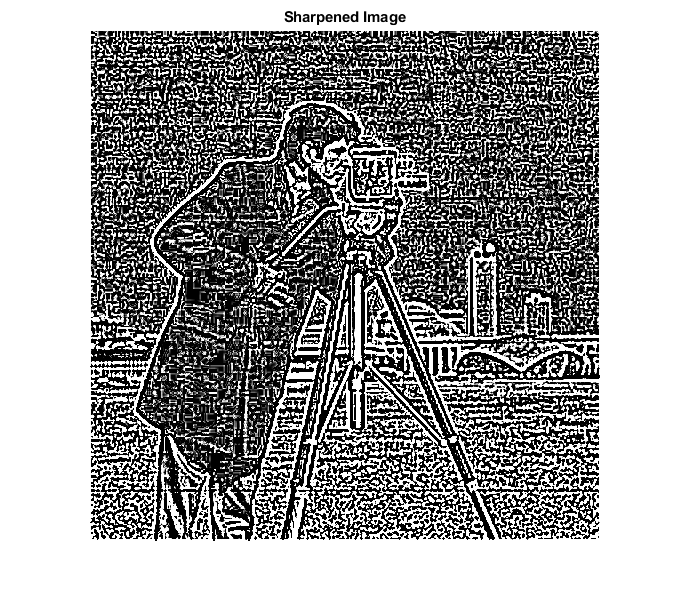


% Unsharp masking step
sh = b - b1;
figure;
imshow(sh);
title('Sharpened Image');

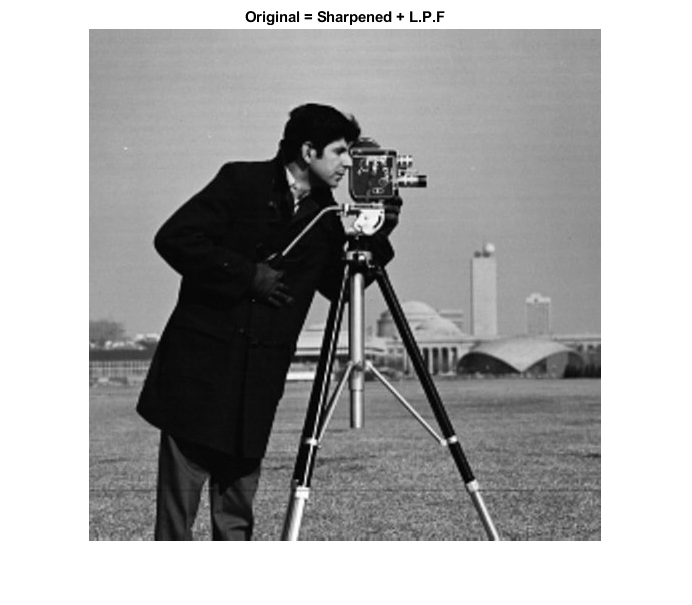


% Getting back our original image

org = sh + b1;
figure;
imshow(uint8(org));
title("Original = Sharpened + L.P.F");